# **Signals and Systems**

## **Experiment No. # 11**

### Objective: 

The objective of this lab is to create a practical understanding of the Discrete Time Fourier  Transform (Chapter 5 of textbook) and to prove some properties of the DTFT. 

### Theoretical Background: 

The Discrete Time Fourier Transform is used for representation of discrete-time a-periodic  signals: DTFT representation of a finite discrete signal (Analysis equation): 

𝑋(𝑒 𝑗𝑤) = ∑ 𝑥[𝑛]𝑒 −𝑗𝑤𝑛 𝑁−1 𝑛=0 

### Calculation of a signal from its DTFT (Synthesis equation): 

𝑥[𝑛] = 1/2𝜋 ∫ 𝑋(𝑒 𝑗𝑤)𝑒 𝑗𝑤𝑛 𝑑𝑤 2𝜋 0 

### Properties of the Discrete Time Fourier Transform: 

There are many properties associated with the DTFT, in this lab the students will prove the  following two properties, where:

 • x[n] and y[n] are two discrete time a-periodic signals

 • 𝑋(𝑒 𝑗𝑤) and 𝑌(𝑒 𝑗𝑤) are the DTFT representation of x[n] and y[n] respectively

####  1. Convolution Property: 

This property states that the DTFT of convolution of two discrete time sequences is equal  to multiplication of the DTFTs of the sequences.

 𝑥[𝑛] ∗ 𝑦[𝑛] = 𝐼𝐷𝑇𝐹𝑇 (𝑋(𝑒 𝑗𝑤)𝑌(𝑒 𝑗𝑤)) 

#### 2. Multiplication Property: 

The DTFT of multiplication of two discrete time a-periodic signals is equal to the  periodic convolution of the DTFT of the individual signals.

 𝑥[𝑛]𝑦[𝑛] = 𝐼𝐷𝑇𝐹𝑇 ( 1/2𝜋 ∫ 𝑋(𝑒 𝑗𝜃)𝑌(𝑒 𝑗(𝑤−𝜃) ) 𝑑𝜃 2𝜋 0 ) 

####  Tasks: 

The following tasks are to be performed by each student. 

#### Task 1: 

Create separate functions in MATLAB for Discrete Time Fourier Transform (DTFT), i.e.  analysis equation, and Inverse Discrete Time Fourier Transform (IDTFT), i.e. synthesis  equation. 

#### Task 2: 

Consider the rectangular pulse: 𝑥[𝑛] = { 1, |𝑛| ≤ 𝑁1 0, |𝑛| > 𝑁1 which is illustrated below for 𝑁1 = 2. Find the DTFT of x[n] using the DTFT function created in Task 1. Then, find the IDFT of  this result using the IDTFT function, also created in Task 1. Using subplot, display the input  signal x[n], and the output of the IDTFT function. The result in both subplots should be  same. This task is an implementation of Example 5.3 of your textbook.

####  Task 3:

 Using the functions created in task 1, prove the convolution and multiplication properties of  the DTFT in separate codes. Display the time domain (n- domain) results in each case using  the subplot command. The specifications of the two signals are given below for both properties separately. 

#### For Convolution Property:

 • x[n]=[1 0 1 0 1] 

• y[n]=[1 1 0 1 0] 

• N is the length of the signal. 

#### For Multiplication Property:

 • x[n]=[1 2 3 1 3] 

• y[n]=[3 4 3 3 2] 

• N is the length of the signal. 

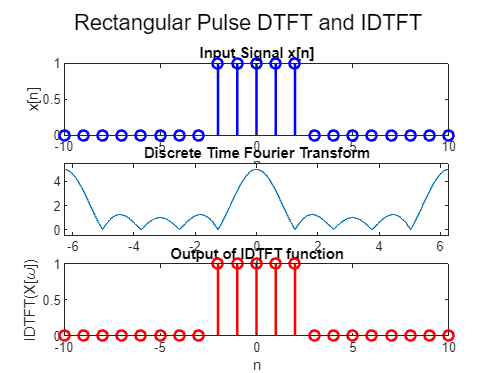

N1 = 2;
n = -10:10;
x_n = (abs(n) <= N1);
N = length(n);

% Find DTFT of x[n]
X_w = DTFT(x_n, N);

% Find IDFT of X(w)
x_reconstructed = IDTFT(X_w, N);

% Plotting
figure;

% Plot input signal x[n]
subplot(3,1,1);
stem(n, x_n, 'b', 'LineWidth', 1.5);
title('Input Signal x[n]');
xlabel('n');
ylabel('x[n]');

%Plot of DTFT function output
subplot(3,1,2)
ezplot(abs(X_w));
title('Discrete Time Fourier Transform');

% Plot output of IDTFT function
subplot(3,1,3);
stem(n, abs(x_reconstructed), 'r', 'LineWidth', 1.5);
title('Output of IDTFT function');
xlabel('n');
ylabel('IDTFT(X[\omega])');

% Adjust subplot layout
sgtitle('Rectangular Pulse DTFT and IDTFT');

% Ensure the plots are on the same scale
axis tight;

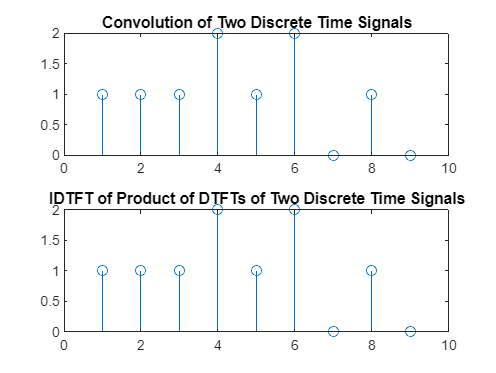

x = [1 0 1 0 1];
N1 = length(x);
y = [1 1 0 1 0];
N2 = length(y);

figure;
% LHS
LHS = conv(x,y);
subplot(2,1,1);
stem(abs(LHS));
title('Convolution of Two Discrete Time Signals');

% RHS
A = DTFT(x,N1);
B = DTFT(y,N2);
C = A .* B;
RHS = IDTFT(C, length(LHS));

subplot(2,1,2);
stem(abs(RHS));
title('IDTFT of Product of DTFTs of Two Discrete Time Signals');

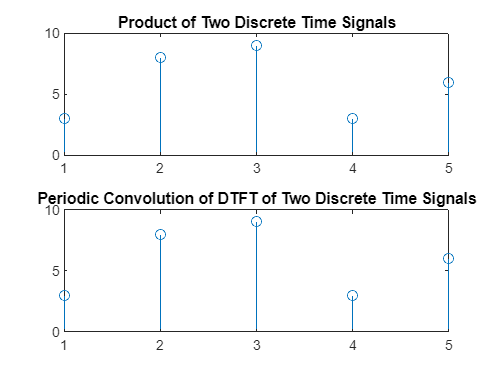

x = [1 2 3 1 3];
N1 = length(x);
y = [3 4 3 3 2];
N2 = length(y);

% LHS
LHS = x .* y;
subplot(2,1,1);
stem(abs(LHS));
title('Product of Two Discrete Time Signals');

% RHS
syms w theta
A = DTFT(x, N1);
C = DTFT(y, N2);
B = subs(A, w, theta);
D = subs(C, w, w-theta);
E = B * D;
F = 1/(2.*pi) .* int(E, theta, 0, 2*pi);
RHS = IDTFT(F,length(LHS));

subplot(2,1,2);
stem(abs(RHS));
title('Periodic Convolution of DTFT of Two Discrete Time Signals');